## Detector de automóviles en una autopista

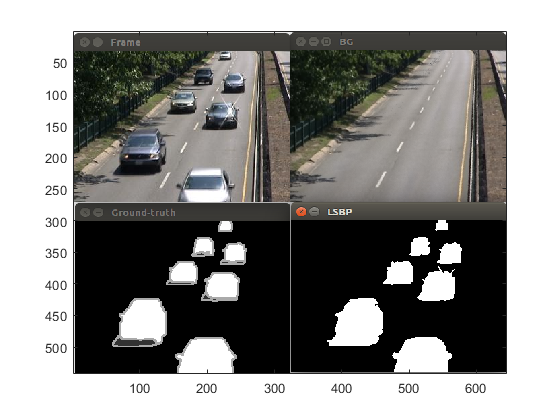

% Conteo de autos 
% Carga imagen y recorta dos zonas: escena con autos, y solo pista
im = imread('cars.png');
image(im)

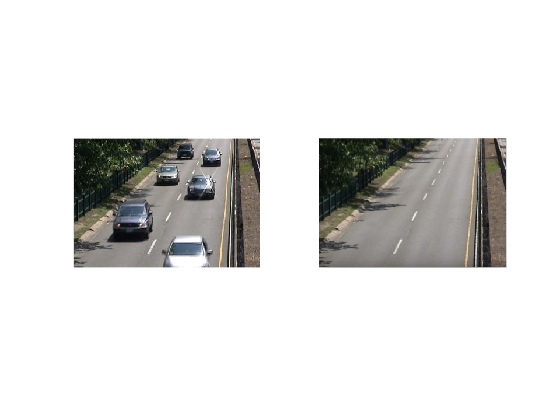

cars = im(51:271, 2:322, :);
pista = im(51:271, 324:644, :);

figure, 
subplot(1, 2, 1), imshow(cars)
subplot(1, 2, 2), imshow(pista)

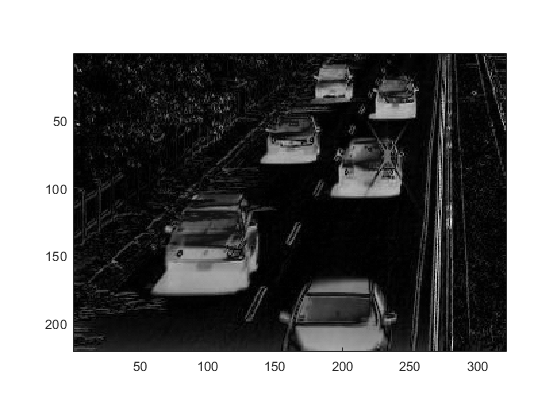


% Suma el absoluto de la diferencia de los 3 planos
dif = sum(abs(double(cars) - double(pista)), 3);
figure, imagesc(dif), colormap gray, axis image

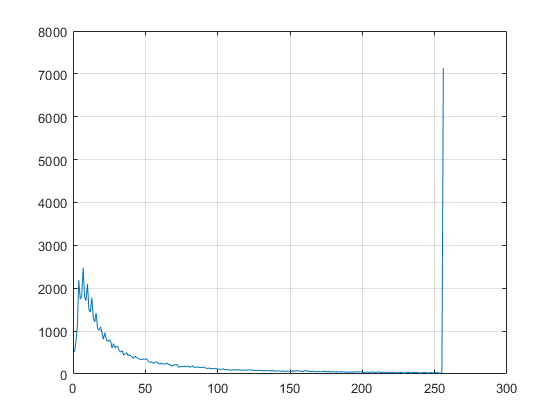


% Histograma
h = imhist(uint8(dif), 256);
figure, plot(h), grid

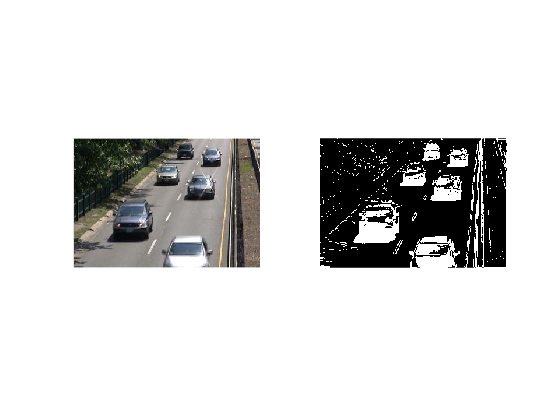


% Umbralizamos para crear mascara de autos con valores sobre 120
mask1 = dif > 120;
figure, 
subplot(1, 2, 1), imshow(cars)
subplot(1, 2, 2), imshow(mask1)

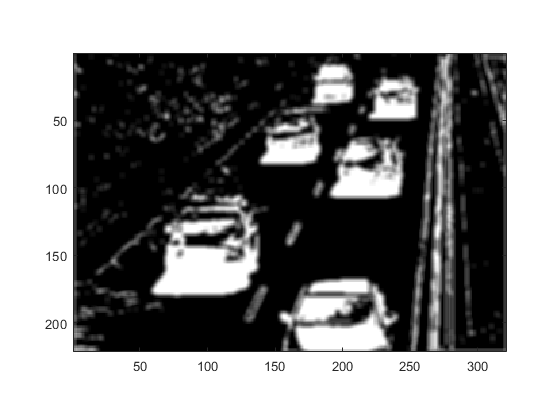


% Filtrado pasabajos gaussiano
k = fspecial('gaussian', 5, 2);
%figure, surf(k)
bmf = filter2(k, mask1);
figure, imagesc(bmf), colormap gray, axis image

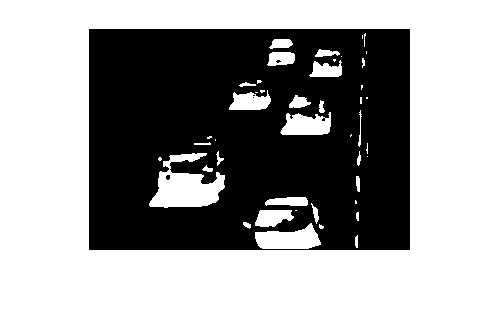


% Volvemos a umbralizar
bm2 = bmf > 0.75;
figure, imshow(bm2),


% Dilatamos con elemento estructural de 11x5 porque queremos fusionar 
% secciones de auto de manera vertical
se = ones(11, 5);
dil1 = imdilate(bm2, se);

% Closing para juntar mejor los autos
se2 = strel('disk', 2, 0)

se2 = strel is a disk shaped structuring element with properties:

      Neighborhood: [5×5 logical]
    Dimensionality: 2


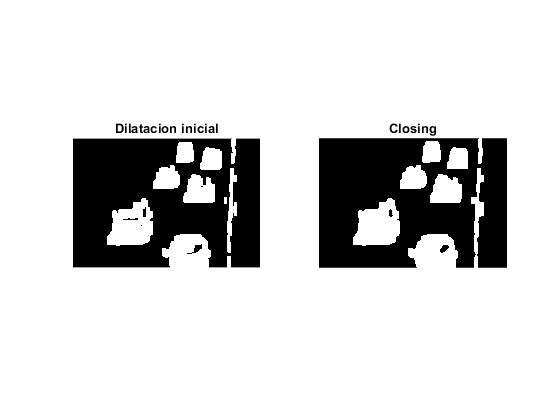

autos1 = imclose(dil1, se2);

figure, 
subplot(1, 2, 1), imshow(dil1), title('Dilatacion inicial')
subplot(1, 2, 2), imshow(autos1), title('Closing')

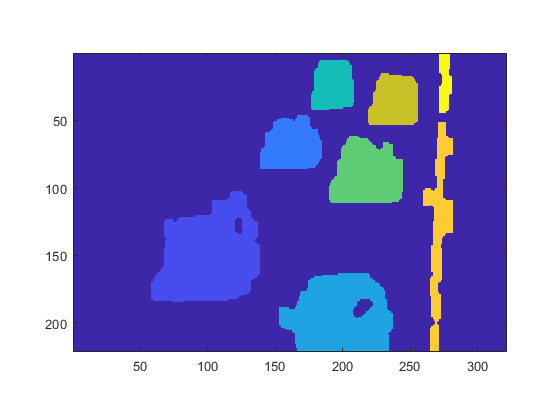


% Etiquetamos cada objeto
L = bwlabel(autos1); 
figure, imagesc(L), axis image

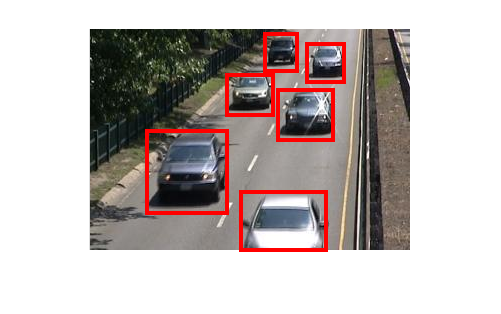


% Obtiene coordenadas, boundingbox y excentricidad del centroide para cada objeto
info = regionprops(autos1, 'Centroid', 'BoundingBox', 'Eccentricity');

% Los objetos con alta excentricidad ( > 0.95) son alargados, como los bordes
n_blobs = max(L(:)); % Determinacion del numero de objetos

for ind = n_blobs:-1:1  % Para borrar desde el ultimo registro
  if info(ind).Eccentricity > 0.95
    info(ind) = []; % Elimina el registro
  end
end

n_cars = length(info);
% Dibuja boundingbox para cada auto
figure, imshow(cars), hold on,
for ind = 1:n_cars  
  rectangle('Position', info(ind).BoundingBox,'EdgeColor','r', 'LineWidth', 3)
end